%%INPUTS

%Flight Conditions
h = 0 %ft

h = 0

V = 100; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0024

V=V*1.688

V = 168.8000

AoA = 0;

%Wing Parameters
QuarterSweep = 0 %deg

QuarterSweep = 0

Df = 15.5;
TaperRatio = 0.4

TaperRatio = 0.4000

S = 1693

S = 1693

b = 118

b = 118

AR = b^2/S

AR = 8.2245

SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepLE = 2.9830

InstallAngle = 2.5

InstallAngle = 2.5000

LiftCurveSlope = 0.0863 %Per deg

LiftCurveSlope = 0.0863


%Prop Parameters
ThrustAngle = 0

ThrustAngle = 0

Rp = 10

Rp = 10

HP = 18698*2 %Per engine

HP = 37396

PropEff = 0.81

PropEff = 0.8100

zProp = 3

zProp = 3


%Thrust = HP*0.81/V*550
Thrust = 18698*2

Thrust = 37396


x1 = 10

x1 = 10

x2 = 10

x2 = 10


ThrustCoef = Thrust/(0.5*AirDens*V^2*S) 

ThrustCoef = 0.6523

PropCorrelationParam = S*ThrustCoef/(8*Rp^2) %Use to find f

PropCorrelationParam = 1.3804

Sp = pi*Rp^2

Sp = 314.1593


%DATCOM Figures
PropNormForceCoeff = 0.5 %Pg 1387 Depends on Nominal Blade Anlgle and # of props

PropNormForceCoeff = 0.5000

PropUpwashGradient = 0.5 %Pg 1275 Depends on AR and Prop Distance from 0.25Cr

PropUpwashGradient = 0.5000

f = 1.75 %Pg 1387 Depends on PropCorrelationParam

f = 1.7500

C1 = 0.4 %Pg 1388 Depends on PropCorrelationParam

C1 = 0.4000

C2 = 0.2 %Pg 1388 Depends on PropCorrelationParam

C2 = 0.2000

K = 1 %Pg 1398 Depends on Si/S

K = 1

K1 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K1 = 0.8000

K2 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K2 = 0.8000


%For clean wing
daCLmax = 1.2

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9

MaxLiftCoefRatio = 0.9000


%Airfoil Parameters
ZeroLiftAngle = -3

ZeroLiftAngle = -3

ClMax = 1.6

ClMax = 1.6000

AirfoilStallAngle = 16

AirfoilStallAngle = 16

Cla = 0.11

Cla = 0.1100



%Clean wing
CLMax = MaxLiftCoefRatio*ClMax

CLMax = 1.4400

WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax

WingStallAngle = 14.8860


%Flapped From Graphs
FlapDeflec = 40 %Deg

FlapDeflec = 40

ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec

dZeroLiftAngle = -18


%%CALCULATIONS

%Flapped Wing
y1flap=Df/2

y1flap = 7.7500

y2flap=0.75*b/2

y2flap = 44.2500

y3flap=0

y3flap = 0

y4flap=0

y4flap = 0


y3Aileron = 56.05

y3Aileron = 56.0500


cr = 2*S/(b*(1+TaperRatio))

cr = 20.4964


c1flap = cr*(1-(1-TaperRatio)*2*y1flap/b)

c1flap = 18.8810

c2flap = cr*(1-(1-TaperRatio)*2*y2flap/b)

c2flap = 11.2730

c3flap = cr*(1-(1-TaperRatio)*2*y3flap/b)

c3flap = 20.4964

c4flap = cr*(1-(1-TaperRatio)*2*y4flap/b)

c4flap = 20.4964


c3Aileron = cr*(1-(1-TaperRatio)*2*y3Aileron/b)

c3Aileron = 8.8134


SWF = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap))

SWF = 1.1006e+03

SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4)

SweepFactor = 0.9200


dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec

dAirfoilStallAngle = -3.1040


AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle

AirfoilStallAngleFlapped = 12.8960


ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle

ZeroLiftAngleFlapped = -21


ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped)

ClMaxFlapped = 3.7286


dClMaxFlapped = ClMaxFlapped - ClMax

dClMaxFlapped = 2.1286

dCLMaxFlapped = dClMaxFlapped*SWF*SweepFactor/S

dCLMaxFlapped = 1.2731


CLMaxFlapped = CLMax + dCLMaxFlapped

CLMaxFlapped = 2.7131


%Powered CLmax



%KN =
KN = 80.7 %ASSUMED

KN = 80.7000


TruePropNormalForceCoeff = PropNormForceCoeff*(1+0.8*(KN/80.7-1))

TruePropNormalForceCoeff = 0.5000


PropPlaneAngle = ThrustAngle + PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)  

PropPlaneAngle = 2.7500


dCLPropNorm = f*TruePropNormalForceCoeff*PropPlaneAngle/57.3*Sp/S*cosd(ThrustAngle)

dCLPropNorm = 0.0078


UpwashGradient = C1 + C2*TruePropNormalForceCoeff

UpwashGradient = 0.5000


PropDownwashAngle = UpwashGradient*PropPlaneAngle

PropDownwashAngle = 1.3750


dWingAoA = -PropDownwashAngle/(1+PropUpwashGradient)

dWingAoA = -0.9167


PropUpwashAngle = PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)

PropUpwashAngle = 2.7500


for x=1:1:27
   
    CL = (x-1)/10
    
    %Inboard Props
    y1 = 19 %ft to centerline of prop
    z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b1 = 2*sqrt(Rp^2-z1^2)
    c1 = cr*(1-(1-TaperRatio)*2*y1/b)
    S1 = b1*c1
    AReff1 = b1/c1
    dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)
    dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1
    dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CL
    
    %Outboard Props
    y2 = 45.5 %ft to centerline of prop
    z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b2 = 2*sqrt(Rp^2-z2^2)
    c2 = cr*(1-(1-TaperRatio)*2*y2/b)
    S2 = b2*c2
    AReff2 = b2/c2
    dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)
    dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1
    dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CL
    
    ImmersedRatio = (2*S1+2*S2)/S
    
    CLPowered(x) = CL + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

    alpha(x) = (CL/LiftCurveSlope)+ZeroLiftAngleFlapped
    
end

CL = 0

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0

ImmersedRatio = 0.6158

CLPowered = -0.1448

alpha = -21

CL = 0.1000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.0520

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.0346

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284


alpha =   -21.0000  -19.8413


CL = 0.2000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.1039

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.0692

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015


alpha =   -21.0000  -19.8413  -18.6825


CL = 0.3000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.1559

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.1038

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747


alpha =   -21.0000  -19.8413  -18.6825  -17.5238


CL = 0.4000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.2079

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.1384

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650


CL = 0.5000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.2599

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.1731

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063


CL = 0.6000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.3118

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.2077

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475


CL = 0.7000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.3638

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.2423

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888


CL = 0.8000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.4158

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.2769

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300


CL = 0.9000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.4677

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.3115

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713


CL = 1

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.5197

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.3461

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125


CL = 1.1000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.5717

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.3807

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538


CL = 1.2000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.6237

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.4153

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950


CL = 1.3000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.6756

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.4499

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363


CL = 1.4000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.7276

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.4846

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775


CL = 1.5000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.7796

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.5192

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188


CL = 1.6000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.8315

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.5538

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600


CL = 1.7000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.8835

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.5884

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013


CL = 1.8000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.9355

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.6230

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425


CL = 1.9000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 0.9874

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.6576

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162


CL = 2

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.0394

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.6922

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750


CL = 2.1000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.0914

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.7268

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185    5.5917


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337


CL = 2.2000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.1434

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.7614

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185    5.5917    5.8648


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925


CL = 2.3000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.1953

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.7961

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185    5.5917    5.8648    6.1380


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512


CL = 2.4000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.2473

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.8307

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185    5.5917    5.8648    6.1380    6.4111


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100


CL = 2.5000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.2993

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.8653

ImmersedRatio = 0.6158

CLPowered =    -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185    5.5917    5.8648    6.1380    6.4111    6.6843


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687


CL = 2.6000

y1 = 19

z1 = 3.2400

b1 = 18.9211

c1 = 16.5361

S1 = 312.8807

AReff1 = 1.1442

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = -0.0528

dCLq1 = 1.3512

y2 = 45.5000

z2 = 3.2400

b2 = 18.9211

c2 = 11.0125

S2 = 208.3680

AReff2 = 1.7182

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = -0.0352

dCLq2 = 0.8999

ImmersedRatio = 0.6158

CLPowered = 1×27
   -0.1448    0.1284    0.4015    0.6747    0.9479    1.2210    1.4942    1.7674    2.0405    2.3137    2.5869    2.8600    3.1332    3.4063    3.6795    3.9527    4.2258    4.4990    4.7722    5.0453    5.3185    5.5917    5.8648    6.1380    6.4111    6.6843    6.9575


alpha = 1×27
  -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


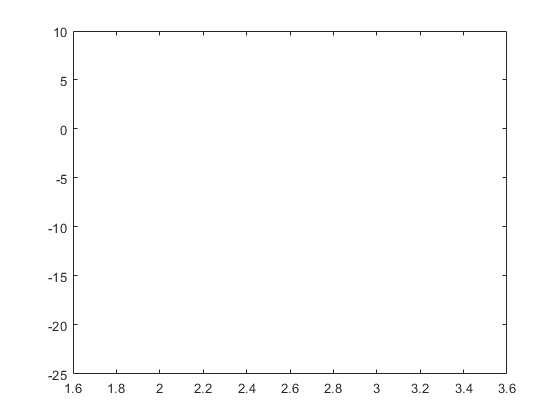


plot(CL,alpha)


%Inboard Props
y1 = 19 %ft to centerline of prop

y1 = 19

z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z1 = 3.2400

b1 = 2*sqrt(Rp^2-z1^2)

b1 = 18.9211

c1 = cr*(1-(1-TaperRatio)*2*y1/b)

c1 = 16.5361

S1 = b1*c1

S1 = 312.8807

AReff1 = b1/c1

AReff1 = 1.1442

dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure1 = 3.5152

dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1

dCLWash1 = -0.0528

dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CLMaxFlapped

dCLq1 = 1.4100


%Outboard Props
y2 = 45.5 %ft to centerline of prop

y2 = 45.5000

z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z2 = 3.2400

b2 = 2*sqrt(Rp^2-z2^2)

b2 = 18.9211

c2 = cr*(1-(1-TaperRatio)*2*y2/b)

c2 = 11.0125

S2 = b2*c2

S2 = 208.3680

AReff2 = b2/c2

AReff2 = 1.7182

dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure2 = 3.5152

dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1

dCLWash2 = -0.0352

dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CLMaxFlapped

dCLq2 = 0.9390


ImmersedRatio = (2*S1+2*S2)/S

ImmersedRatio = 0.6158


CLMaxPowered = CLMaxFlapped + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

CLMaxPowered = 7.2664